University of Science and Technology in Zewail City

Communication and Information Engineering Program

CIE 247: [Digital Signal Processing - Spring 2026](https://classroom.google.com/u/1/c/ODI1MzU5NDE0MDQ0)

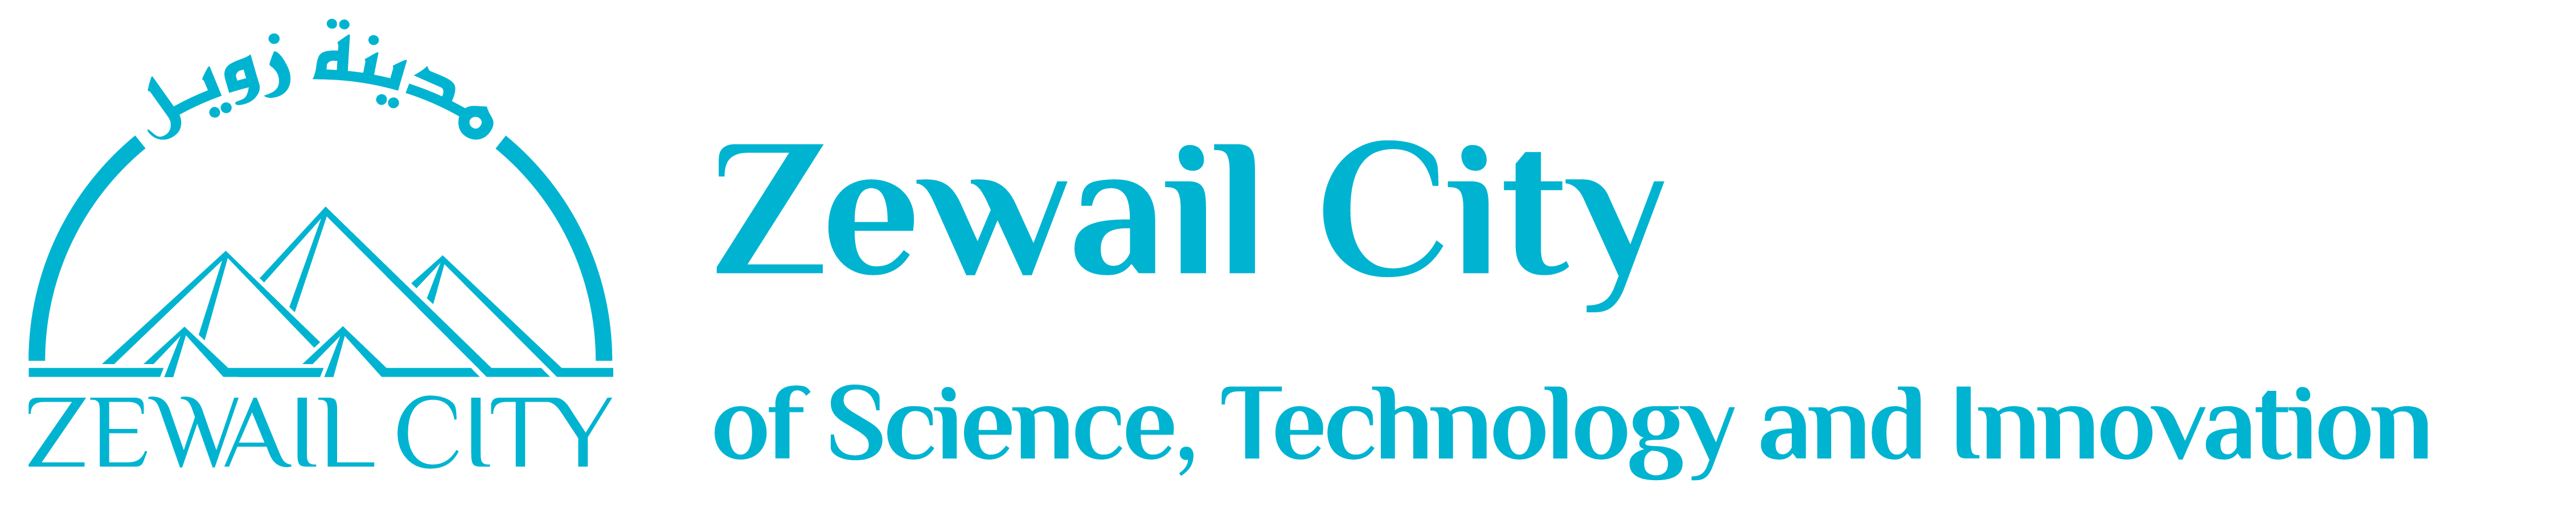

## Project Title: Multi-Band Speech Equalizer for Podcast Enhancement

Author: Mohamed Salah-202400614

Supervision: Prof. Ahmed Eltrass, Eng. Retaj Yousri, Eng. Eman Abdelnaby

clear; close all; clc;

### User Input.

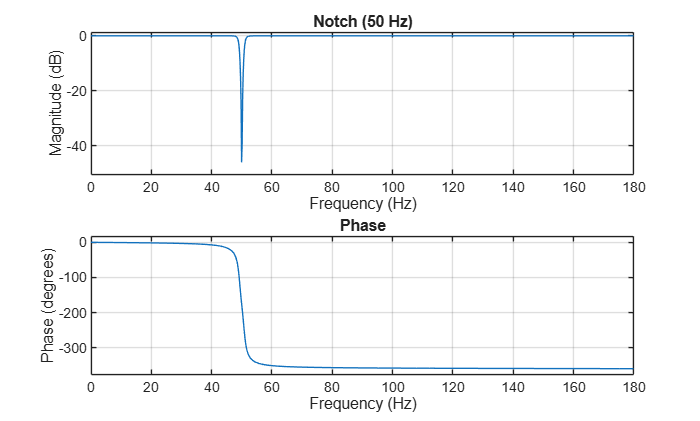

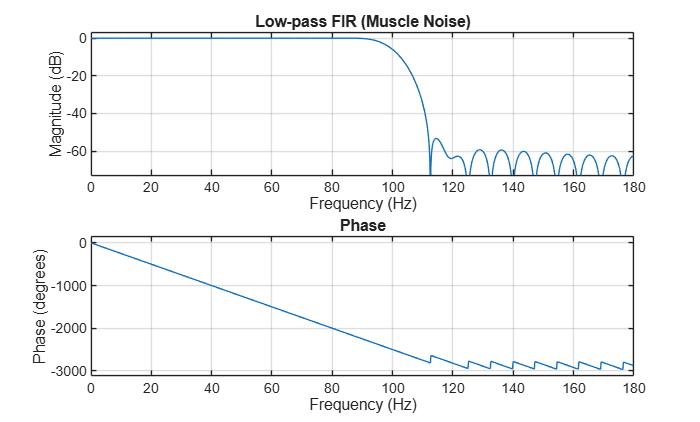

fprintf('========================================\n');
fprintf('  Multi-Band Speech Equalizer for Podcast\n');
fprintf('========================================\n\n');

% Get audio file name
audio_file = input('Enter audio file name (with extension, e.g., speech.wav): ', 's');

% Check if file exists
while ~exist(audio_file, 'file')
    fprintf('File not found!\n');
    audio_file = input('Enter audio file name (with extension, e.g., speech.wav): ', 's');
end

% Mode selection
fprintf('\nModes of Operation:\n');
fprintf('1 - Preset Mode (Speech-Optimized Bands)\n');
fprintf('2 - Custom Mode\n');

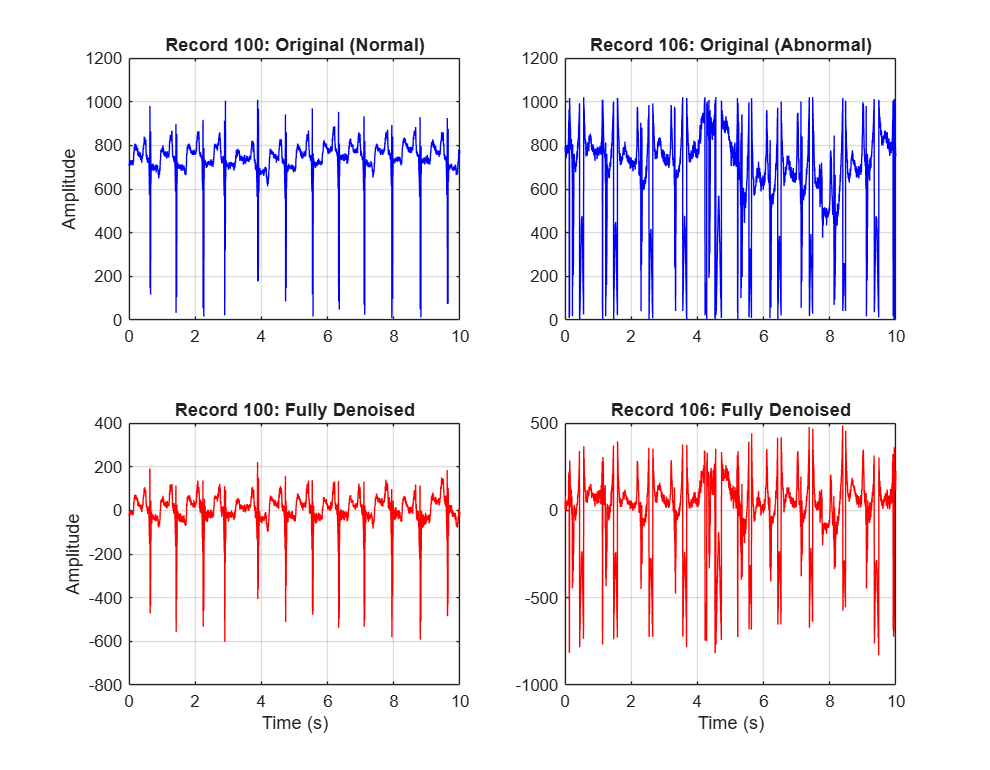

mode = input('Select mode (1 or 2): ');

if mode == 1
    % Preset frequency bands
    bands = [0 100; 100 300; 300 800; 800 2000; 2000 5000; 5000 10000; 10000 20000];
    num_bands = size(bands, 1);
    fprintf('\nPreset bands (Hz):\n');
    for i = 1:num_bands
        fprintf('Band %d: %d - %d Hz\n', i, bands(i,1), bands(i,2));
    end
    % Default gains for speech enhancement
    default_gains = [-3, -2, 0, 3, 5, 4, 2]; % dB
    fprintf('\nDefault gains for speech clarity: ');
    fprintf('%.1f ', default_gains);
    fprintf('dB\n');
    use_default = input('Use default gains? (y/n): ', 's');
    if lower(use_default) == 'y'
        gains = default_gains;
    else
        gains = zeros(1, num_bands);
        for i = 1:num_bands
            gains(i) = input(sprintf('Enter gain for band %d (%d-%d Hz) in dB: ', i, bands(i,1), bands(i,2)));
        end
    end

elseif mode == 2
    % Custom bands
    num_bands = input('Enter number of bands (5-10): ');
    while num_bands < 5 || num_bands > 10
        num_bands = input('Invalid! Enter number of bands (5-10): ');
    end
    bands = zeros(num_bands, 2);
    bands(1,1) = 0;
    bands(end,2) = 20000;
    for i = 1:num_bands
        if i == 1
            bands(i,2) = input(sprintf('Enter end frequency for band %d (Hz): ', i));
        elseif i == num_bands
            bands(i,1) = bands(i-1,2);
        else
            bands(i,1) = bands(i-1,2);
            bands(i,2) = input(sprintf('Enter end frequency for band %d (Hz): ', i));
        end
    end
    gains = zeros(1, num_bands);
    for i = 1:num_bands
        gains(i) = input(sprintf('Enter gain for band %d (%d-%d Hz) in dB: ', i, bands(i,1), bands(i,2)));
    end
end

% Filter type selection
fprintf('\nFilter Type:\n');
fprintf('1 - FIR\n');
fprintf('2 - IIR\n');
filter_type = input('Select filter type (1 or 2): ');
while ~ismember(filter_type, [1,2])
    filter_type = input('Invalid! Select 1 or 2: ');
end

% Sub-type selection
if filter_type == 1
    fprintf('\nFIR Window Type:\n');
    fprintf('1 - Hamming\n');
    fprintf('2 - Hanning\n');
    fprintf('3 - Blackman\n');
    win_choice = input('Select window (1, 2, or 3): ');
    while ~ismember(win_choice, [1,2,3])
        win_choice = input('Invalid! Select 1, 2, or 3: ');
    end
    switch win_choice
        case 1, win_type = 'hamming';
        case 2, win_type = 'hann';
        case 3, win_type = 'blackman';
    end
else
    fprintf('\nIIR Design Method:\n');
    fprintf('1 - Butterworth\n');
    fprintf('2 - Chebyshev Type I\n');
    fprintf('3 - Chebyshev Type II\n');
    iir_choice = input('Select design (1, 2, or 3): ');
    while ~ismember(iir_choice, [1,2,3])

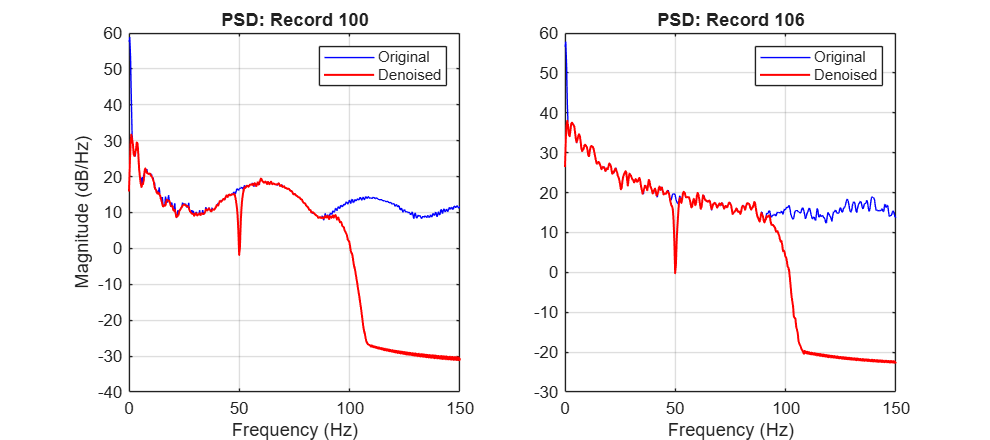

        iir_choice = input('Invalid! Select 1, 2, or 3: ');
    end
    switch iir_choice

        case 1, iir_type = 'butter';
        case 2, iir_type = 'cheby1';
        case 3, iir_type = 'cheby2';

Denoising Results (Estimated SNR After Filtering)


Record 100 (Normal) SNR:   -19.8639 dB


Record 106 (Abnormal) SNR: -10.1548 dB


    end
end

% Filter order
filter_order = input('Enter filter order (default = 100 for FIR, 4 for IIR, press Enter for default): ');
if isempty(filter_order)
    if filter_type == 1
        filter_order = 100;
    else
        filter_order = 4;
    end
end

% Output sample rate
fs_out = input('Enter output sample rate (Hz, press Enter for original): ');
if isempty(fs_out)
    fs_out = [];
end

### Reading Audio File.

[audio_in, fs_in] = audioread(audio_file);
fprintf('\nOriginal sample rate: %d Hz\n', fs_in);

% Convert to mono if stereo
if size(audio_in, 2) > 1
    audio_in = mean(audio_in, 2);
end

% Resample if needed
if ~isempty(fs_out) && fs_out ~= fs_in
    audio_in = resample(audio_in, fs_out, fs_in);
    fs_in = fs_out;
end

% Normalize audio
audio_in = audio_in / max(abs(audio_in));

### Designing Filters and Process Signal.

fprintf('\nProcessing...\n');

% Initialize output signal
audio_out = zeros(size(audio_in));

% Store filter coefficients for analysis
filter_coeffs = cell(1, num_bands);

% Process each band
nyquist = fs_in / 2;
for b = 1:num_bands
    fprintf('Processing band %d/%d: %d-%d Hz', b, num_bands, bands(b,1), bands(b,2));

    % Skip bands entirely above Nyquist
    if bands(b,1) >= nyquist
        fprintf(' -> SKIPPED (above Nyquist = %d Hz)\n', round(nyquist));
        filter_coeffs{b} = struct('b', 1, 'a', 1);
        continue;
    end

    fprintf('\n');

    % Design filter
    if filter_type == 1
        [b_coeff, a_coeff] = design_fir_filter(bands(b,:), filter_order, fs_in, win_type);
    else
        [b_coeff, a_coeff] = design_iir_filter(bands(b,:), filter_order, fs_in, iir_type);
    end

    filter_coeffs{b} = struct('b', b_coeff, 'a', a_coeff);

    % Apply filter
    filtered_signal = filter(b_coeff, a_coeff, audio_in);

    % Replace any NaN/Inf with 0
    filtered_signal(~isfinite(filtered_signal)) = 0;

    % Apply gain (convert dB to linear)
    gain_linear = 10^(gains(b)/20);
    filtered_signal = filtered_signal * gain_linear;

    fprintf('    -> Band %d energy: %.6f | Gain applied: %.2f dB (x%.3f)\n', ...
        b, rms(filtered_signal), gains(b), gain_linear);

    % Sum to output
    audio_out = audio_out + filtered_signal;
end

% Replace any remaining NaN/Inf
audio_out(~isfinite(audio_out)) = 0;

% Normalize output to prevent clipping
max_val = max(abs(audio_out));
if max_val > 0
    audio_out = audio_out / max_val;
end

% --- DIAGNOSTIC: Show difference ---
fprintf('\n--- DIAGNOSTIC ---\n');
fprintf('  Input  RMS: %.6f  |  Max: %.6f\n', rms(audio_in), max(abs(audio_in)));
fprintf('  Output RMS: %.6f  |  Max: %.6f\n', rms(audio_out), max(abs(audio_out)));
diff_signal = audio_out - audio_in;
fprintf('  Difference RMS: %.6f  (0 = identical, >0 = changed)\n', rms(diff_signal));
if rms(diff_signal) < 1e-6
    fprintf('  WARNING: Output is nearly identical to input!\n');
else
    fprintf('  OK: Output is different from input.\n');
end
fprintf('------------------\n');

### Filter Analysis.

fprintf('\n--- Filter Analysis ---\n');
if filter_type == 1
    type_str = sprintf('FIR (%s)', win_type);
else
    type_str = sprintf('IIR (%s)', iir_type);
end
analyze_filters(filter_coeffs, bands, type_str, filter_order, fs_in);

### Signal Processing Steps Visualization.

fprintf('\n--- Signal Processing Analysis ---\n');
analyze_signals(audio_in, audio_out, fs_in, bands, gains);

### Performance Evaluation.

fprintf('\n--- Performance Evaluation ---\n');
evaluate_performance(audio_in, audio_out, fs_in);

### ` Play and Save Output`.

fprintf('\n--- Playback and Save ---\n');
play_and_save(audio_in, audio_out, fs_in, audio_file);

### Demonstration Requirements.

fprintf('\n--- Demonstration ---\n');
demonstrate_capabilities(audio_file, audio_in, gains, bands, fs_in);

fprintf('\n========================================\n');
fprintf('  PROCESSING COMPLETE\n');
fprintf('========================================\n');

### Helper Functions.

function [b, a] = design_fir_filter(band, order, fs, win_type)
    % Design FIR filter using specified window
    nyquist = fs/2;
    f1 = band(1) / nyquist;
    f2 = min(band(2), nyquist - 1) / nyquist;  % Clamp upper edge to Nyquist

    % Clamp to valid range for fir1
    f1 = max(0.001, min(0.999, f1));
    f2 = max(0.002, min(0.999, f2));

    % Ensure f1 < f2
    if f1 >= f2, f1 = f2 - 0.01; end
    if f1 <= 0, f1 = 0.001; end

    % Create window
    w = feval(win_type, order+1);

    if band(1) == 0
        b = fir1(order, f2, 'low', w);
    elseif band(2) >= nyquist
        b = fir1(order, f1, 'high', w);
    else
        b = fir1(order, [f1 f2], 'bandpass', w);
    end
    a = 1;
end

function [b, a] = design_iir_filter(band, order, fs, iir_type)
    % Design IIR filter using specified method
    nyquist = fs/2;
    f1 = max(0.001, min(0.99, band(1) / nyquist));
    f2 = max(0.01, min(0.99, min(band(2), nyquist - 1) / nyquist));

    % Ensure f1 < f2
    if f1 >= f2, f1 = f2 - 0.01; end
    if f1 <= 0, f1 = 0.001; end

    if band(1) == 0
        switch iir_type
            case 'butter', [b, a] = butter(order, f2, 'low');
            case 'cheby1', [b, a] = cheby1(order, 0.5, f2, 'low');
            case 'cheby2', [b, a] = cheby2(order, 40, f2, 'low');
        end
    elseif band(2) >= nyquist
        switch iir_type
            case 'butter', [b, a] = butter(order, f1, 'high');
            case 'cheby1', [b, a] = cheby1(order, 0.5, f1, 'high');
            case 'cheby2', [b, a] = cheby2(order, 40, f1, 'high');
        end
    else
        if f1 >= f2, f1 = f2 - 0.01; end
        switch iir_type
            case 'butter', [b, a] = butter(order, [f1 f2], 'bandpass');
            case 'cheby1', [b, a] = cheby1(order, 0.5, [f1 f2], 'bandpass');
            case 'cheby2', [b, a] = cheby2(order, 40, [f1 f2], 'bandpass');
        end
    end
end

function analyze_filters(filter_coeffs, bands, type_str, order, fs)
    % Generate all 6 analysis plots for EACH band
    num_bands = length(filter_coeffs);

    for b = 1:num_bands
        figure('Name', sprintf('Band %d: %d-%d Hz', b, bands(b,1), bands(b,2)), ...
               'Position', [50+15*b, 50+15*b, 1100, 700]);

        bc = filter_coeffs{b}.b;
        ac = filter_coeffs{b}.a;

        % Magnitude Response
        subplot(2,3,1);
        [h, w] = freqz(bc, ac, 2048, fs);
        plot(w, 20*log10(abs(h) + eps), 'b', 'LineWidth', 1.2);
        xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
        title('Magnitude Response'); grid on; xlim([0 fs/2]);

        % Phase Response
        subplot(2,3,2);
        plot(w, unwrap(angle(h))*180/pi, 'r', 'LineWidth', 1.2);
        xlabel('Frequency (Hz)'); ylabel('Phase (degrees)');
        title('Phase Response'); grid on; xlim([0 fs/2]);

        % Impulse Response
        subplot(2,3,3);
        impLen = min(200, length(bc)*3);
        imp = [1; zeros(impLen-1, 1)];
        h_imp = filter(bc, ac, imp);
        stem(0:impLen-1, h_imp, 'filled', 'MarkerSize', 3);
        xlabel('Samples'); ylabel('Amplitude');
        title('Impulse Response'); grid on;

        % Step Response
        subplot(2,3,4);
        step_in = ones(impLen, 1);
        h_step = filter(bc, ac, step_in);
        plot(0:impLen-1, h_step, 'g', 'LineWidth', 1.5);
        xlabel('Samples'); ylabel('Amplitude');
        title('Step Response'); grid on;

        % Filter Info
        subplot(2,3,5);
        axis off;
        text(0.1, 0.5, {sprintf('Filter: %s', type_str), ...
             sprintf('Order: %d', order), ...
             sprintf('Band: %d - %d Hz', bands(b,1), bands(b,2)), ...
             sprintf('Num coeffs: %d', length(bc)), ...
             sprintf('Den coeffs: %d', length(ac))}, ...
             'FontSize', 11, 'FontName', 'Consolas', 'Units', 'normalized');
        title('Filter Information');

        % Pole-Zero Plot
        subplot(2,3,6);
        zplane(bc, ac);
        title('Pole-Zero Plot');

        sgtitle(sprintf('Band %d: %d-%d Hz  |  %s  |  Order %d', ...
                b, bands(b,1), bands(b,2), type_str, order), ...
                'FontSize', 13, 'FontWeight', 'bold');
    end
end

function analyze_signals(audio_in, audio_out, fs, bands, gains)
    % Sanitize signals - replace NaN/Inf with 0
    audio_in(~isfinite(audio_in)) = 0;
    audio_out(~isfinite(audio_out)) = 0;

    fprintf('1. Band filters designed\n');
    fprintf('2. Input signal filtered\n');
    fprintf('3. Gain applied to each band\n');
    fprintf('4. Filtered bands combined in time domain\n');

    % 5. Compare original and processed signals
    figure('Name', 'Signal Comparison', 'Position', [100, 100, 1200, 800]);

    N = min(length(audio_in), length(audio_out));
    t = (0:N-1)/fs;

    % Time domain - full
    subplot(2,2,1);
    plot(t, audio_in(1:N), 'b'); hold on;
    plot(t, audio_out(1:N), 'r');
    xlabel('Time (s)'); ylabel('Amplitude');
    title('Time Domain Comparison');
    legend('Original', 'Processed'); grid on;

    % Frequency domain
    subplot(2,2,2);
    f = (0:N/2-1) * fs / N;
    Y_in = fft(audio_in(1:N));
    Y_out = fft(audio_out(1:N));
    plot(f, 20*log10(abs(Y_in(1:N/2)) + eps), 'b'); hold on;
    plot(f, 20*log10(abs(Y_out(1:N/2)) + eps), 'r');
    xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
    title('Frequency Domain Comparison');
    legend('Original', 'Processed'); grid on; xlim([0 fs/2]);

    % 6. Power Spectral Density
    subplot(2,2,3);
    [pxx_in, f_psd] = pwelch(audio_in, hamming(1024), 512, 1024, fs);
    [pxx_out, ~] = pwelch(audio_out, hamming(1024), 512, 1024, fs);
    plot(f_psd, 10*log10(pxx_in + eps), 'b'); hold on;
    plot(f_psd, 10*log10(pxx_out + eps), 'r');
    xlabel('Frequency (Hz)'); ylabel('Power/Freq (dB/Hz)');
    title('Power Spectral Density');
    legend('Original', 'Processed'); grid on; xlim([0 fs/2]);

    % 7. Spectrogram - Original
    subplot(2,2,4);
    spectrogram(audio_in, hamming(512), 256, 512, fs, 'yaxis');
    title('Original Spectrogram'); colormap jet;

    % Spectrogram - Processed (separate figure)
    figure('Name', 'Processed Spectrogram', 'Position', [150, 150, 600, 400]);
    spectrogram(audio_out, hamming(512), 256, 512, fs, 'yaxis');
    title('Processed Spectrogram'); colormap jet;

    % Print gain settings
    fprintf('\nGain Settings Applied:\n');
    for i = 1:length(gains)
        fprintf('  Band %d (%d-%d Hz): %.1f dB\n', i, bands(i,1), bands(i,2), gains(i));
    end
end

function evaluate_performance(audio_in, audio_out, fs)
    % Sanitize signals
    audio_in(~isfinite(audio_in)) = 0;
    audio_out(~isfinite(audio_out)) = 0;

    fprintf('\n--- Performance Metrics ---\n');

    N = min(length(audio_in), length(audio_out));
    Y_in = fft(audio_in(1:N));
    Y_out = fft(audio_out(1:N));
    f = (0:N/2-1) * fs / N;
    mag_in = 20*log10(abs(Y_in(1:N/2)) + eps);
    mag_out = 20*log10(abs(Y_out(1:N/2)) + eps);

    % Spectral energy per band
    freq_bands = [0 100; 100 300; 300 800; 800 2000; 2000 5000; 5000 10000; 10000 20000];
    fprintf('\nSpectral Energy Changes:\n');
    fprintf('%-15s %15s %15s %15s\n', 'Band (Hz)', 'Original (dB)', 'Processed (dB)', 'Change (dB)');
    fprintf('%s\n', repmat('-', 1, 65));
    for b = 1:size(freq_bands, 1)
        idx = find(f >= freq_bands(b,1) & f <= freq_bands(b,2));
        if ~isempty(idx)
            avg_in = mean(mag_in(idx));
            avg_out = mean(mag_out(idx));
            fprintf('%-15s %15.2f %15.2f %15.2f\n', ...
                sprintf('%d-%d', freq_bands(b,1), freq_bands(b,2)), avg_in, avg_out, avg_out - avg_in);
        end
    end

    % Spectral centroid
    fprintf('\nSpectrogram Analysis:\n');
    [S_in, F_s, ~] = spectrogram(audio_in(1:N), 256, 128, 256, fs);
    [S_out, ~, ~]  = spectrogram(audio_out(1:N), 256, 128, 256, fs);
    cent_in  = sum(F_s .* mean(abs(S_in), 2)) / sum(mean(abs(S_in), 2));
    cent_out = sum(F_s .* mean(abs(S_out), 2)) / sum(mean(abs(S_out), 2));
    fprintf('Spectral centroid - Original: %.1f Hz, Processed: %.1f Hz\n', cent_in, cent_out);

    % Listening evaluation guide
    fprintf('\n--- Listening Evaluation Guide ---\n');
    fprintf('Listen for:\n');
    fprintf('  - Speech clarity and intelligibility\n');
    fprintf('  - Presence of sibilance ("s", "sh", "ch" sounds)\n');
    fprintf('  - Plosive clarity ("p", "t", "k" sounds)\n');
    fprintf('  - Background noise level\n');
    fprintf('  - Overall naturalness and warmth\n');

    % Artifacts analysis
    fprintf('\n--- Artifacts and Distortion Analysis ---\n');
    signal_power = sum(audio_in(1:N).^2);
    noise_power = sum((audio_out(1:N) - audio_in(1:N)).^2);
    if noise_power > 0
        SNR = 10*log10(signal_power / noise_power);
    else
        SNR = inf;
    end
    fprintf('Signal-to-Noise Ratio (processing artifacts): %.2f dB\n', SNR);

    if max(abs(audio_out)) > 0.99
        fprintf('WARNING: Output signal near clipping (max = %.3f)\n', max(abs(audio_out)));
    else
        fprintf('No clipping detected (max = %.3f)\n', max(abs(audio_out)));
    end

    % Trade-offs
    fprintf('\n--- Trade-offs Discussion ---\n');
    fprintf('- FIR: linear phase, stable, but needs higher order for sharp cutoff\n');
    fprintf('- IIR: efficient, lower order, but nonlinear phase, potential instability\n');
    fprintf('- High boost (>6 dB): enhanced clarity but possible harshness\n');
    fprintf('- Low cut (<100 Hz): removes rumble but may lose warmth\n');
    fprintf('- Upsampling (4x): preserves quality but increases file size\n');
    fprintf('- Downsampling (0.5x): reduces bandwidth, possible aliasing\n');
    fprintf('- Chebyshev filters: sharper cutoff but introduce passband ripple\n');
end

function play_and_save(audio_in, audio_out, fs, original_filename)
    % Save output file FIRST so user can compare externally
    [path, name, ext] = fileparts(original_filename);
    if isempty(path), path = pwd; end
    output_filename = fullfile(path, sprintf('%s_equalized%s', name, ext));
    audiowrite(output_filename, audio_out, fs);
    fprintf('\n  Saved equalized audio to: %s\n', output_filename);
    fprintf('  TIP: Open both files in any media player to compare!\n');
    fprintf('    Original:  %s\n', original_filename);
    fprintf('    Processed: %s\n\n', output_filename);

    % Playback
    fprintf('Press Enter to play ORIGINAL audio...\n');
    pause;
    clear sound;  % Stop any previous playback
    sound(audio_in, fs);
    fprintf('>> Playing ORIGINAL...\n');
    pause(length(audio_in)/fs + 1);

    fprintf('Press Enter to play PROCESSED audio...\n');
    pause;
    clear sound;  % Stop any previous playback
    sound(audio_out, fs);
    fprintf('>> Playing PROCESSED...\n');
    pause(length(audio_out)/fs + 1);
end

function demonstrate_capabilities(audio_file, audio_in, gains, bands, fs)
    fprintf('\n--- Demonstration of Capabilities ---\n');
    num_bands = size(bands, 1);

    % ---- FIR Demo ----
    fprintf('\n[FIR Demonstration - Hamming Window]\n');
    fir_out = zeros(size(audio_in));
    for b = 1:num_bands
        [bc, ac] = design_fir_filter(bands(b,:), 100, fs, 'hamming');
        sig = filter(bc, ac, audio_in) * 10^(gains(b)/20);
        fir_out = fir_out + sig;
    end
    fir_out = fir_out / max(abs(fir_out));
    audiowrite('demo_FIR_equalized.wav', fir_out, fs);
    fprintf('  Saved: demo_FIR_equalized.wav\n');

    % ---- IIR Demo ----
    fprintf('\n[IIR Demonstration - Butterworth]\n');
    iir_out = zeros(size(audio_in));
    for b = 1:num_bands
        [bc, ac] = design_iir_filter(bands(b,:), 4, fs, 'butter');
        sig = filter(bc, ac, audio_in) * 10^(gains(b)/20);
        iir_out = iir_out + sig;
    end
    iir_out = iir_out / max(abs(iir_out));
    audiowrite('demo_IIR_equalized.wav', iir_out, fs);
    fprintf('  Saved: demo_IIR_equalized.wav\n');

    % ---- Sample rate x4 ----
    fs_x4 = fs * 4;
    audio_x4 = resample(audio_in, 4, 1);
    audiowrite('demo_x4_rate.wav', audio_x4, fs_x4);
    fprintf('\n  Output sample rate x4: %d -> %d Hz\n', fs, fs_x4);
    fprintf('  Saved: demo_x4_rate.wav\n');

    % ---- Sample rate /2 ----
    fs_half = round(fs / 2);
    audio_half = resample(audio_in, 1, 2);
    audiowrite('demo_half_rate.wav', audio_half, fs_half);
    fprintf('  Output sample rate /2: %d -> %d Hz\n', fs, fs_half);
    fprintf('  Saved: demo_half_rate.wav\n');

    % ---- Comparison figure ----
    figure('Name', 'Sample Rate Demo', 'Position', [100, 100, 1200, 700]);
    sgtitle('Sample Rate Conversion Demonstration', 'FontWeight', 'bold');

    subplot(3,1,1);
    t1 = (0:length(audio_in)-1)/fs;
    plot(t1, audio_in, 'b'); grid on;
    title(sprintf('Original: %d Hz', fs));
    xlabel('Time (s)'); ylabel('Amplitude');

    subplot(3,1,2);
    t2 = (0:length(audio_x4)-1)/fs_x4;
    plot(t2, audio_x4, 'Color', [0 0.6 0]); grid on;
    title(sprintf('4x Rate: %d Hz', fs_x4));
    xlabel('Time (s)'); ylabel('Amplitude');

    subplot(3,1,3);
    t3 = (0:length(audio_half)-1)/fs_half;
    plot(t3, audio_half, 'r'); grid on;
    title(sprintf('Half Rate: %d Hz', fs_half));
    xlabel('Time (s)'); ylabel('Amplitude');
end